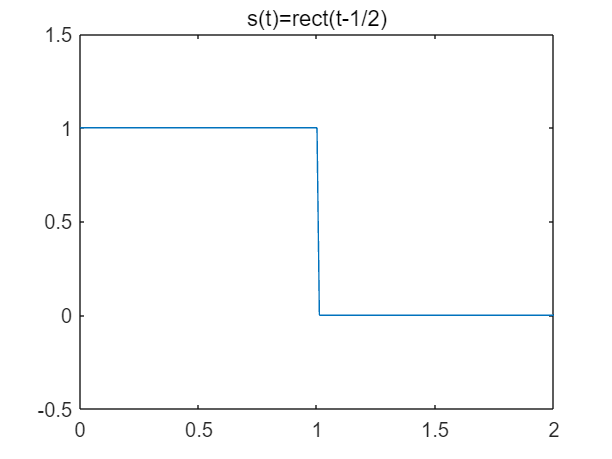

%3.2.1
t1=0:0.01:2;
s1=(abs(t1-1/2)<=1/2);
t2=0:0.01:1;
s2=(abs(2*t2)<=1/2) + (abs(2*(t2-1))<=1/2) - 1/2;

figure
plot(t1,s1)
axis([0,2,-0.5,1.5])
title('s(t)=rect(t-1/2)')

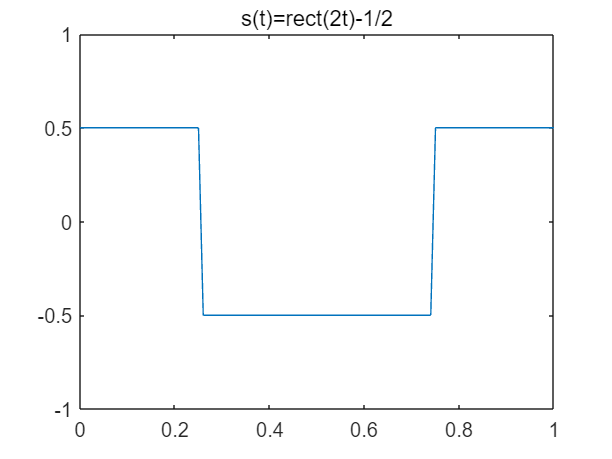

figure
plot(t2,s2)
axis([0,1,-1,1])
title('s(t)=rect(2t)-1/2')

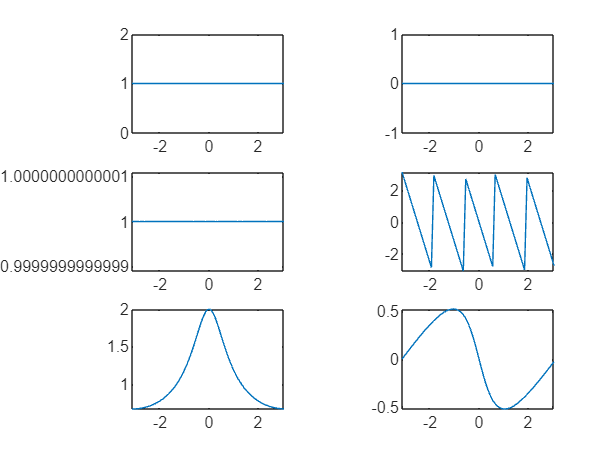

%3.5
w = -1*pi:0.1:pi;
n=-10:10;
n2=-10:50;
x1=(n==0);
x2=(n==5);
x3=0.5.^n2.*(n2>=0);
X1=DTFT(x1,n(1),0.1);
X2=DTFT(x2,n(1),0.1);
X3=DTFT(x3,n2(1),0.1);
figure
subplot(3,2,1)
plot(w,abs(X1))
subplot(3,2,2)
plot(w,angle(X1))
subplot(3,2,3)
plot(w,abs(X2))
subplot(3,2,4)
plot(w,angle(X2))
subplot(3,2,5)
plot(w,abs(X3))
subplot(3,2,6)
plot(w,angle(X3))

function X=DTFT(x,n0,dw)
w = -1*pi:dw:pi;
i = sqrt(-1);
n=n0:length(x)+n0-1;
X = zeros(1,length(w));
for k=1:length(w)
X(k)= sum(x.*exp(-i*w(k)*n));
end
end
